clc;
clear all;
close all;

% training data
hatchedClassificationOne = [0 0 0 1 1 1 1 1 1 0];
hatchedClassificationTwo = [1 2 1 0 1 1 0];
hatchedClassificationThree = [1 0 1 1 0 1 1];
hatchedClassificationFour = [1 0 1 1 1 0 1];
hatchedClassificationFive = [1 1 1 1 1 1 1 2 0];
hatchedClassificationSix = [0 1 0 0 1 0 1 0];
hatchedClassificationSeven = [1 0 1 1 1 1 1 1 1 1 0 1];

hatchedClassification = [hatchedClassificationOne hatchedClassificationTwo hatchedClassificationThree hatchedClassificationFour hatchedClassificationFive hatchedClassificationSix hatchedClassificationSeven];

expectedResultOneToTen = [
    11, 10, 6;
    7,  8,  6;
    12, 8,  5;
    11, 7,  4;
    11, 9,  6;
    9,  8,  3;
    16, 11, 9;
    13, 11, 11;
    13, 13, 9;
    17, 14, 6
];


imageFiles = dir('/Users/falkrehm/Library/Mobile Documents/com~apple~CloudDocs/Studium/SoSe_25/BVM/Praktikum/Praktikum4/Testbilder/*.tif'); % or *.png, *.bmp etc.
images = cell(1, numel(imageFiles));

for k = 1:numel(imageFiles)
    imgPath = fullfile(imageFiles(k).folder, imageFiles(k).name);
    images{k} = imread(imgPath);
end

% extract features from eggs for Images 1-7 to train
statTable = [];

i = 1;

for imageCell = images(1:7)
    I = cell2mat(imageCell);
    eggStats = extractEggAttributes(I, 0);
    for eggStat = eggStats
        statLine = [i eggStat.mean eggStat.deviation eggStat.missingArea];
        statTable = cat(1, statTable, statLine);
    end
    
    i = i + 1;

end

features = statTable(statTable(:, 1) <= 7, 2:4); % exclude ID/index
validIdx = hatchedClassification ~= 2;
filteredFeatures = features(validIdx, :);
filteredLabels = hatchedClassification(validIdx);

hatchedClassification

hatchedClassification =      0     0     0     1     1     1     1     1     1     0     1     2     1     0     1     1     0     1     0     1     1     0     1     1     1     0     1     1     1     0     1     1     1     1     1     1     1     1     2     0     0     1     0     0     1     0     1     0     1     0


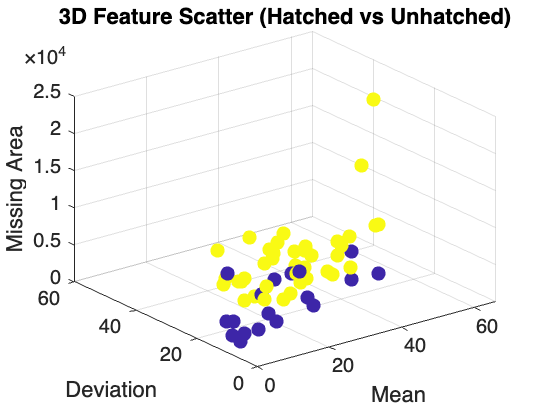


% Visualize 3D scatter with filtered labels
figure;
% gscatter3 shortcut function
gscatter3 = @(x,y,z,c) scatter3(x,y,z,50,c,'filled');
gscatter3(filteredFeatures(:,1), filteredFeatures(:,2), filteredFeatures(:,3), filteredLabels);
xlabel('Mean'); ylabel('Deviation'); zlabel('Missing Area');
title('3D Feature Scatter (Hatched vs Unhatched)');
grid on;

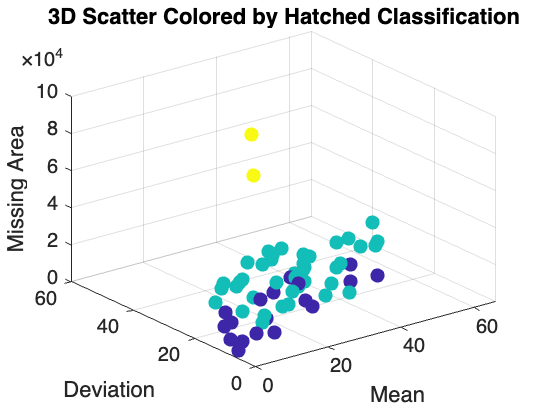


% Visualize 3D scatter with all labels
figure;
gscatter3(features(:,1), features(:,2), features(:,3), hatchedClassification);
xlabel('Mean'); ylabel('Deviation'); zlabel('Missing Area');
title('3D Scatter Colored by Hatched Classification');

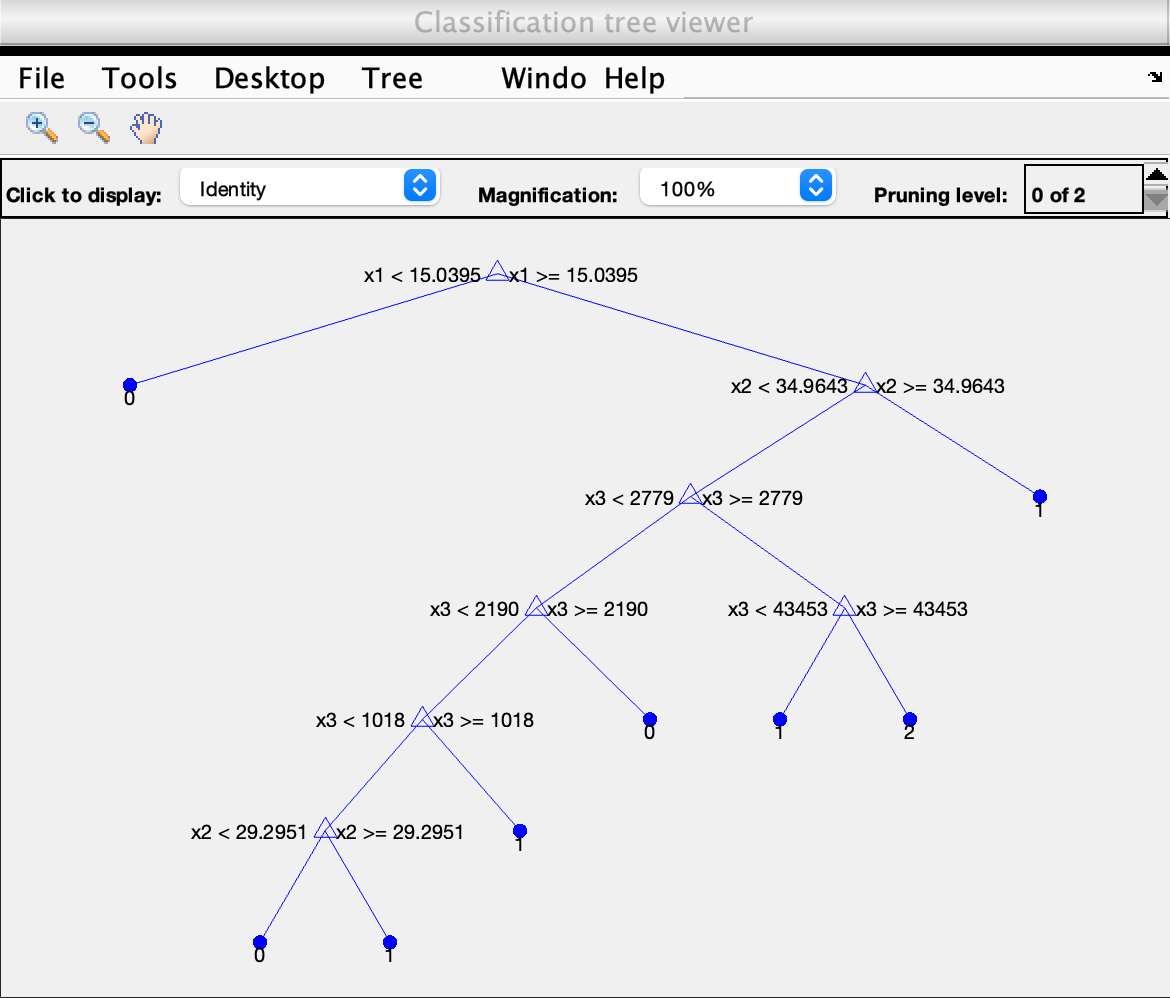

% AI Training
features = statTable(statTable(:,1) <= 7, 2:4);

%X = features(hatchedClassification, :);     % Features (mean, deviation, missing area)
%Y = hatchedClassification(hatchedClassification);  % Labels (0 or 1)

X = features;

Y = hatchedClassification;

model = fitctree(X, Y);
view(model, 'Mode', 'graph'); % visualize tree


cvmodel = crossval(model, 'KFold', 5); % 5-fold cross-validation

loss = kfoldLoss(cvmodel); % Classification loss (error rate)
fprintf('Cross-validation loss: %.2f%%\n', loss * 100);

Cross-validation loss: 26.67%


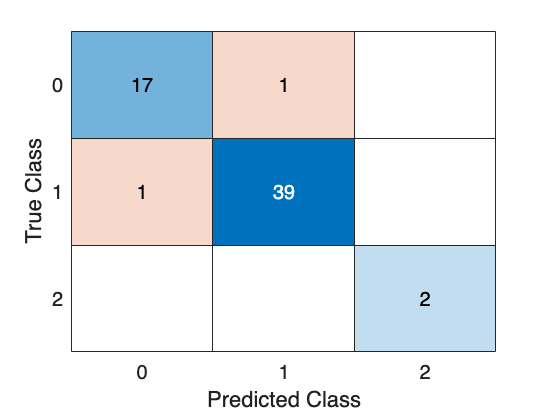


% prediciton on new data
Ypred = predict(model, X); % predict on training data (or test data)

% Confusion matrix
figure;
confusionchart(Y, Ypred);

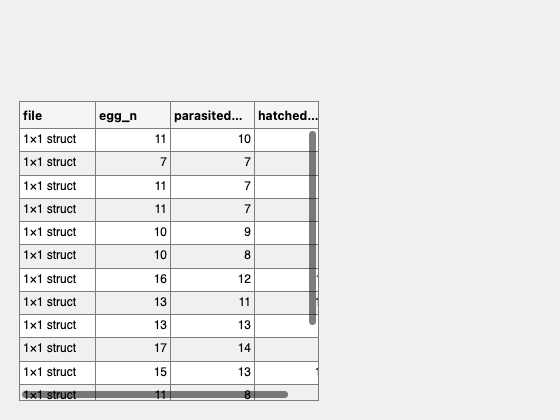

% predict on all images

i = 1;

result = [];

result_line.file = "";
result_line.egg_n = 0;
result_line.parasited_n = 0;
result_line.hatched_n = 0;

for imageCell = images
    I = cell2mat(imageCell);
    eggStats_new = extractEggAttributes(I, 0);
    
    X_new = [];
    
    for eggStat = eggStats_new
        featureLine = [eggStat.mean eggStat.deviation eggStat.missingArea];
        X_new = cat(1, X_new, featureLine);
    end

    if ~isempty(X_new)
        Y_pred_new = predict(model, X_new);
        
        result_line.file = imageFiles(i);
        result_line.egg_n = countEggs(I);
        [result_line.parasited_n, w] = size(Y_pred_new);
        result_line.hatched_n = sum(Y_pred_new == 1);
    
        result = [result result_line];
    end

    i = i + 1;
end

T = struct2table(result);
f = uifigure;             % create figure
t = uitable(f, 'Data', T); % create table in figure

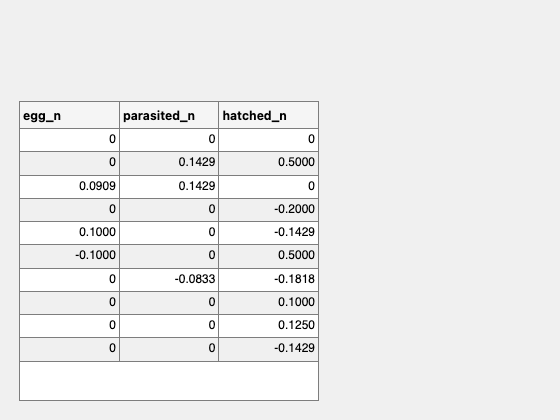


resultOneToTen = T(1:10, 2:end);
mismatch = expectedResultOneToTen - resultOneToTen;
mismatchPercentages = mismatch ./ resultOneToTen;

f2 = uifigure;             % create figure
t2 = uitable(f2, 'Data', mismatchPercentages); % create table in figure

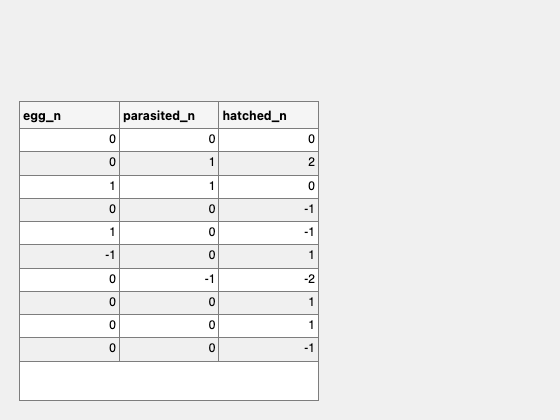


f3 = uifigure;
t3 = uitable(f3, 'Data', mismatch);